clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 5.3 3.5];
figpos = [0.18 0.25 0.69 0.65];
lw = 0.8;

filenames = ["ESN10data" "ESN20data" "ESN50data" "ESN500data"];
colors = linspecer(3);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

errors = [];

for i = 1:4
    load("data\fig3_" + filenames(i) + ".mat", 'edtwlorenzlist');
    k = find(edtwlorenzlist<15.6006);
    k = find(edtwlorenzlist<30.9705);
    k = find(edtwlorenzlist>80 & edtwlorenzlist<1000);
    edtwlorenzlist(k) = 80;
    k = find(edtwlorenzlist>1000 | isnan(edtwlorenzlist));
    edtwlorenzlist(k) = 100;
    errors = [errors edtwlorenzlist']; 
end

v = violin(errors, 'facecolor', [0.5 0.5 0.5], 'edgecolor', [0.5 0.5 0.5], 'bw', 5, 'plotlegend', false, 'mc', [], 'medc', []);

b = 5

same bandwidth bw = 5 used for all cols


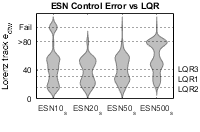

for i = 1:4
    v(i).LineStyle = "-";
end
hold on;
pl = yline(100,':');
pl.Color = [0 0 0];
hold on;
pl = yline(80,':');
pl.Color = [0 0 0];
hold on;
pl = yline(30.9705,':');
pl.Color = [0 0 0];
hold on;
pl = yline(15.6006,':');
pl.Color = [0 0 0];
hold on;
pl = yline(40.5452,':');
pl.Color = [0 0 0];

ylim([0 120]);
yticks([0:40:80 100]);
yticklabels({'0', '40', '>80', 'Fail'});
ylabel('Lorenz track e_{dtw}');
xticklabels({'ESN10_s', 'ESN20_s', 'ESN50_s', 'ESN500_s'});
% violin(errors, 'facecolor', [0.5 0.5 0.5], 'edgecolor', [0.5 0.5 0.5], 'bw', 3, 'plotlegend', false);

yyaxis right;
ylim([0 120]);
yticks([14 28 42]);
yticklabels({'LQR2', 'LQR1', 'LQR3'});

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
ax.YAxis(2).TickLength = [0 0];
ax.YAxis(2).TickLabelInterpreter = 'tex';
title('ESN Control Error vs LQR');
ax.XTickLabelRotation = 0;

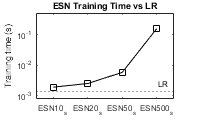

times = [];
for i = 1:4
    load("data\fig3_" + filenames(i) + ".mat", 'trainingtimesdtw');
    times = [times mean(trainingtimesdtw(2:end))]; % 0.0014 0.00193013793103448	0.00253874482758621	0.00584684137931035	0.155980044827586
end

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

times = log10(times);
p = plot(times, '-square');
p.Color = [0 0 0];
c = p.Color;
hold on;
p2 = yline(log10(0.0014),':','LR', FontSize=6, FontName='arial');
p2.Color = [0 0 0];
ylim([-3.1 -0.3]);
yticks(-3:-1);
yticklabels({'10^{-3}', '10^{-2}', '10^{-1}'});
ylabel('Training time (s)');
xticks(1:4);
xticklabels({'ESN10_s', 'ESN20_s', 'ESN50_s', 'ESN500_s'});

xlim([0.5 4.5]);
title('ESN Training Time vs LR');
ax = gca;
ax.XTickLabelRotation = 0;